n = 10;
tic;
result = fibonacci_rec(n);
time_rec = toc

time_rec = 0.0042

disp(['The ', num2str(n), '-th Fibonacci number is: ', num2str(result)]);

The 10-th Fibonacci number is: 55



tic;
result2 = 1/sqrt(5) * (((1+sqrt(5))/2)^n - ((1-sqrt(5))/2)^n)

result2 = 55.0000

time_pat = toc

time_pat = 0.0035

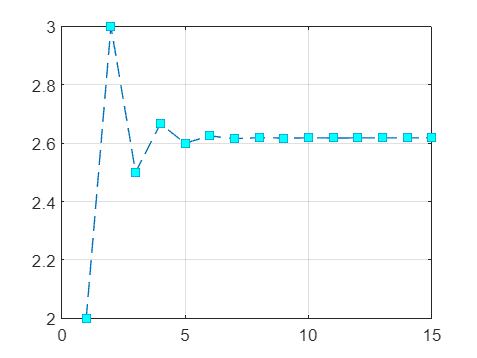


dd = 15;

fibn = zeros(1,dd+1);
for n = 1:dd+1
    fibn(n) = 1/sqrt(5) * (((1+sqrt(5))/2)^n - ((1-sqrt(5))/2)^n);
end

res = zeros(1,dd);
x = zeros(1,dd);
for i = 1:dd
    res(i) = 1 + (fibn(i+1)/fibn(i));
    x(i) = fibn(i+1)/fibn(i);
end

figure;
plot(1:dd, res, "sq--", "MarkerFaceColor", "c");
grid on;

function f = fibonacci_rec(n)
    % Sprawdzenie czy n jest nieujemną liczbą całkowitą
    if n < 0 || mod(n,1) ~= 0
        error('Wejście musi być liczbą naturalną!');
    end
    
    if n == 0
        f = 0;
    elseif n == 1
        f = 1;
    else
        % Rekurencyjne wywołanie funkcji
        f = fibonacci_rec(n-1) + fibonacci_rec(n-2);
    end
end